# Example raster plots showing mean responses & the effect of shuffling

d = SessManager.load_special('Mouse2022', 'events_transients');

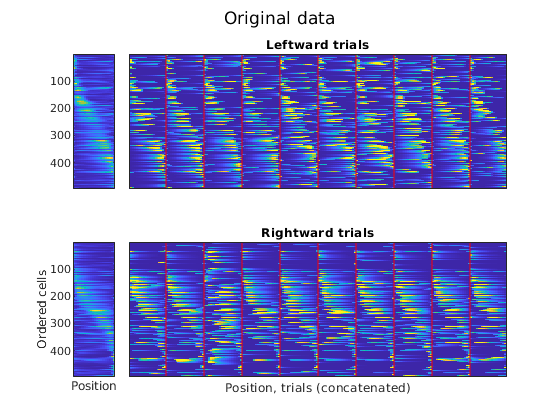

DecodeTensor.tensor_vis(d.data_tensor, d.tr_dir, @(x)x, 8);
sgtitle('Original data');
Utils.printto('events_figs/rasters', 'real_rasters.pdf');

T_shuf = DecodeTensor.shuffle_tensor_common(d.data_tensor, d.tr_dir);

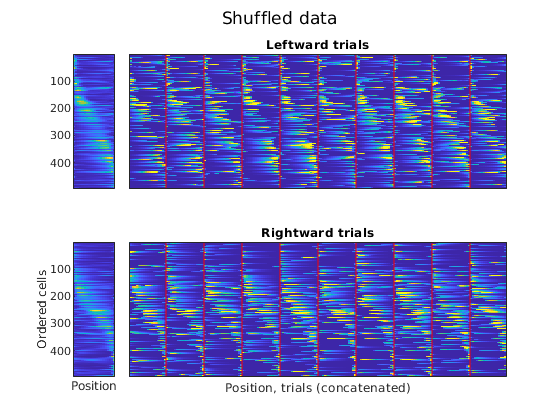

DecodeTensor.tensor_vis(T_shuf, d.tr_dir, @(x)x, 8);
sgtitle('Shuffled data');
Utils.printto('events_figs/rasters', 'shuf_rasters.pdf');

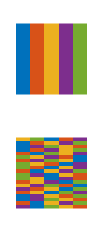

C = 5;
R = 20;
schematic_trials = (1:C) + zeros(R,1);
figure('Units',"inches", "Position",[0 0 1 2.5]);
subplot(2,1,1);
imagesc(schematic_trials);
colormap(lines(5));
set(gca, 'visible', 'off');
axis square

schematic_trials_shuf = schematic_trials;
old_rng = rng;
rng(0);
for i = 1:R
    schematic_trials_shuf(i, :) = schematic_trials_shuf(i, randperm(C));
end
rng(old_rng);
subplot(2,1,2);
imagesc(schematic_trials_shuf);
colormap(lines(5));
set(gca, 'visible', 'off');
axis square

right_tensor = d.data_tensor(:,:,d.tr_dir==1);
flatten = @(t) reshape(t, [size(t,1), size(t,2)*size(t,3)]);

right_meanact = mean(right_tensor, 3);

[~,b_] = max(right_meanact,[],2);
[~,o_right] = sort(b_);

right_meanact = right_meanact(o_right,:);
right_tensor = right_tensor(o_right,:,:);

T_shuf = DecodeTensor.shuffle_tensor_common(d.data_tensor, d.tr_dir);

right_tensor_shuf = T_shuf(:,:,d.tr_dir==1);
right_meanact_shuf = mean(right_tensor_shuf, 3);
[~,b_] = max(right_meanact_shuf,[],2);
[~,o_right_shuf] = sort(b_);
assert(isequal(o_right, o_right_shuf));
right_meanact_shuf = right_meanact_shuf(o_right, :);
right_tensor_shuf = right_tensor_shuf(o_right, :, :);


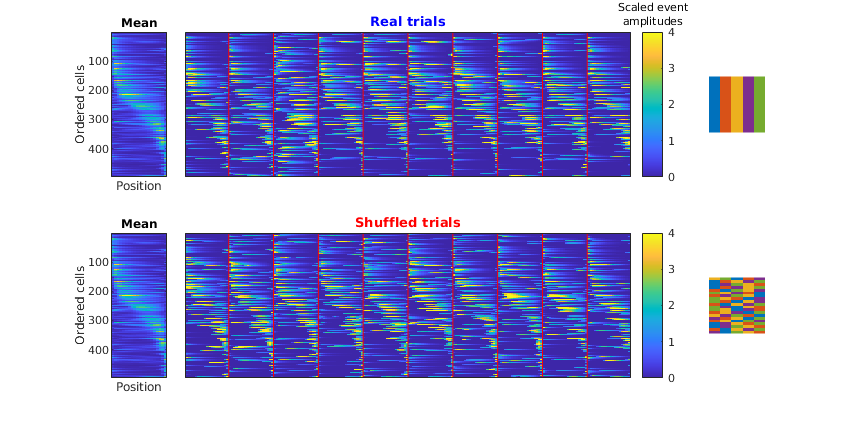

figure('Units', 'inches', 'Position', [26.1562    4.0312    8.8021    4.4271]);
w = 9;
sub_t = 10; start_at = 15;
clim = [0 4];

subplot(2,w,1 ); imagesc(right_meanact, clim); xlabel 'Position'; ylabel 'Ordered cells'; title 'Mean'
set(gca, 'XTick', []);
subplot(2,w,w+1); imagesc(right_meanact_shuf, clim); xlabel 'Position'; ylabel 'Ordered cells'; title 'Mean'
set(gca, 'XTick', []);

if w < 2
    return;
end
subplot(2,w,2:w-1); imagesc(flatten(right_tensor), clim);
xlim([1 sub_t*size(right_tensor,2)] + start_at*size(right_tensor,2));
title 'Real trials' 'Color' 'b'
for i = 1:sum(d.tr_dir == 1)
    hold on;
    l_ = line([20*i 20*i]+0.5, ylim);
    l_.Color = 'r';
end
set(gca, 'XTick', []);
set(gca, 'YTick', []);
h = colorbar;
title(h, sprintf('Scaled event\namplitudes'));

subplot(2,w,w+2:2*w-1); imagesc(flatten(right_tensor_shuf), clim);
xlim([1 sub_t*size(right_tensor_shuf,2)] + start_at*size(right_tensor_shuf,2));
title 'Shuffled trials' 'Color' 'r'
for i = 1:sum(d.tr_dir == 1)
    hold on;
    l_ = line([20*i 20*i]+0.5, ylim);
    l_.Color = 'r';
end
set(gca, 'XTick', []);
set(gca, 'YTick', []);
colorbar;


subplot(2,w,w);
imagesc(schematic_trials);
colormap(gca, lines(5));
set(gca, 'visible', 'off');
axis square

subplot(2,w,2*w);
imagesc(schematic_trials_shuf);
colormap(gca, lines(5));
set(gca, 'visible', 'off');
axis square
Utils.printto('events_figs/rasters', 'trial_shuffle_on_data.pdf');

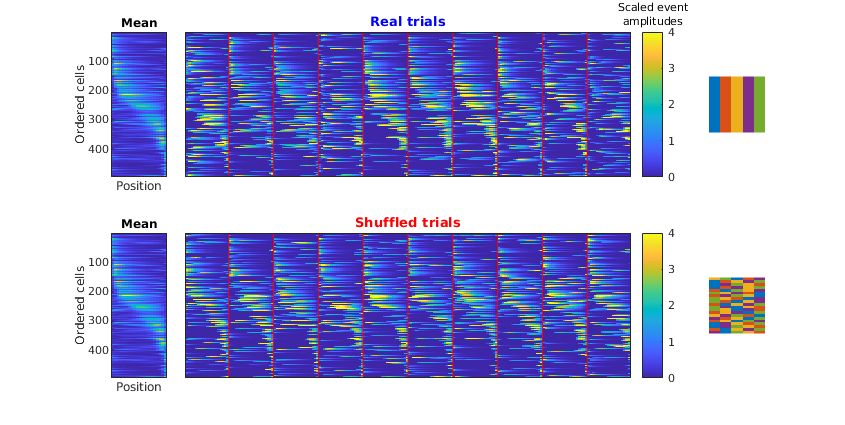

figure('Units', 'inches', 'Position', [26.1562    4.0312    8.8021    4.4271]);
w = 9;
sub_t = 10;

showing_idx = [18 34 49 64 74 85 90 145 154 185];

clim = [0 4];

subplot(2,w,1 ); imagesc(right_meanact, clim); xlabel 'Position'; ylabel 'Ordered cells'; title 'Mean'
set(gca, 'XTick', []);
subplot(2,w,w+1); imagesc(right_meanact_shuf, clim); xlabel 'Position'; ylabel 'Ordered cells'; title 'Mean'
set(gca, 'XTick', []);

if w < 2
    return;
end
subplot(2,w,2:w-1); imagesc(flatten(right_tensor(:,:,showing_idx)), clim);
xlim([1 sub_t*size(right_tensor,2)]);
title 'Real trials' 'Color' 'b'
for i = 1:numel(showing_idx)
    hold on;
    l_ = line([20*i 20*i]+0.5, ylim);
    l_.Color = 'r';
end
set(gca, 'XTick', []);
set(gca, 'YTick', []);
h = colorbar;
title(h, sprintf('Scaled event\namplitudes'));

subplot(2,w,w+2:2*w-1); imagesc(flatten(right_tensor_shuf(:,:,showing_idx)), clim);
xlim([1 sub_t*size(right_tensor_shuf,2)]);
title 'Shuffled trials' 'Color' 'r'
for i = 1:numel(showing_idx)
    hold on;
    l_ = line([20*i 20*i]+0.5, ylim);
    l_.Color = 'r';
end
set(gca, 'XTick', []);
set(gca, 'YTick', []);
colorbar;


subplot(2,w,w);
imagesc(schematic_trials);
colormap(gca, lines(5));
set(gca, 'visible', 'off');
axis square

subplot(2,w,2*w);
imagesc(schematic_trials_shuf);
colormap(gca, lines(5));
set(gca, 'visible', 'off');
axis square
Utils.printto('events_figs/rasters', 'trial_shuffle_on_data_selected.pdf');

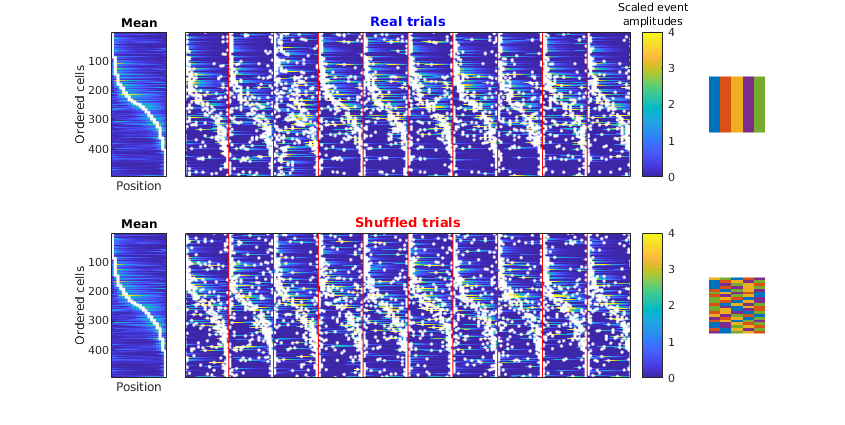

figure('Units', 'inches', 'Position', [26.1562    4.0312    8.8021    4.4271]);
w = 9;
sub_t = 10; start_at = 15;
clim = [0 4];

subplot(2,w,1 ); imagesc(right_meanact, clim); xlabel 'Position'; ylabel 'Ordered cells'; title 'Mean'
cofluct_lines_plot_page(right_meanact);
set(gca, 'XTick', []);
subplot(2,w,w+1); imagesc(right_meanact_shuf, clim); xlabel 'Position'; ylabel 'Ordered cells'; title 'Mean'
cofluct_lines_plot_page(right_meanact_shuf);
set(gca, 'XTick', []);

if w < 2
    return;
end
sp(1) = subplot(2,w,2:w-1); imagesc(flatten(right_tensor), clim);
cofluct_lines_plot(right_tensor);
xlim([1 sub_t*size(right_tensor,2)] + start_at*size(right_tensor,2));
title 'Real trials' 'Color' 'b'
for i = 1:sum(d.tr_dir == 1)
    hold on;
    l_ = line([20*i 20*i]+0.5, ylim);
    l_.Color = 'r';
end
set(gca, 'XTick', []);
set(gca, 'YTick', []);
h = colorbar;
title(h, sprintf('Scaled event\namplitudes'));

sp(2) = subplot(2,w,w+2:2*w-1); imagesc(flatten(right_tensor_shuf), clim);
cofluct_lines_plot(right_tensor_shuf);
xlim([1 sub_t*size(right_tensor_shuf,2)] + start_at*size(right_tensor_shuf,2));
title 'Shuffled trials' 'Color' 'r'
for i = 1:sum(d.tr_dir == 1)
    hold on;
    l_ = line([20*i 20*i]+0.5, ylim);
    l_.Color = 'r';
end
set(gca, 'XTick', []);
set(gca, 'YTick', []);
colorbar;
linkaxes(sp);

subplot(2,w,w);
imagesc(schematic_trials);
colormap(gca, lines(5));
set(gca, 'visible', 'off');
axis square

subplot(2,w,2*w);
imagesc(schematic_trials_shuf);
colormap(gca, lines(5));
set(gca, 'visible', 'off');
axis square
Utils.printto('events_figs/rasters', 'trial_shuffle_on_data.pdf');

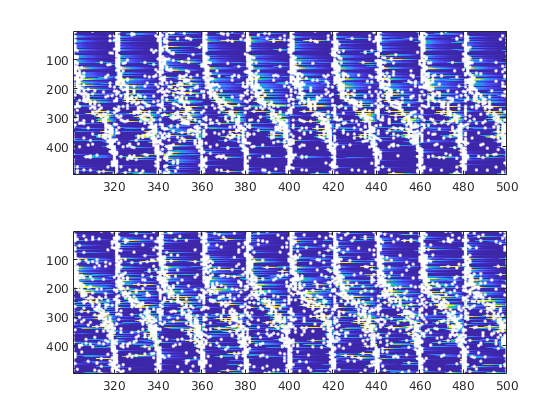

figure;
sp(1) = subplot(2,1,1);
imagesc(flatten(right_tensor), clim);

hold on;
cofluct_lines_plot(right_tensor);
xlim([1 sub_t*size(right_tensor,2)] + start_at*size(right_tensor,2));

sp(2) = subplot(2,1,2);
imagesc(flatten(right_tensor_shuf), clim);

hold on;
cofluct_lines_plot(right_tensor_shuf);
xlim([1 sub_t*size(right_tensor_shuf,2)] + start_at*size(right_tensor_shuf,2));
linkaxes(sp);

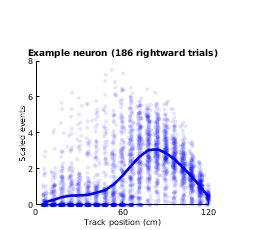

figure;
ix = 285;
plot((1:20)*6, right_meanact(ix,:), 'b', 'LineWidth', 2);
hold on;
x = squeeze(right_tensor(ix,:,:));
k = (1:20).' + zeros(1,size(x,2));
scatter(k(:)*6, x(:), 10, 'b', 'filled',...
    'XJitter', 'randn', 'XJitterWidth', 6);
alpha(0.1);
xlim([0 120]);
set(gca, 'XTick', [0 60 120]);
set(gca, 'YTick', [0,2,4,6,8]);
set(gca, 'Box', 'off');
xlabel 'Track position (cm)'
ylabel 'Scaled events'
title 'Example neuron (186 rightward trials)'
figure_format([1.8 1.5]);
Utils.printto('events_figs/rasters', 'one_cell_variability.pdf');

S = load(d.source_path);

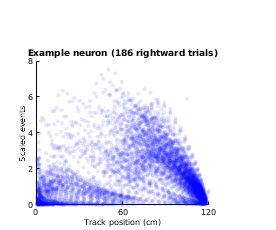

ix = 326;

ntype = 'events_transients';
tr = S.tracesEvents.(ntype)(:,ix);
%tr = S.tracesEvents.events_transients(:,ix);

pos = S.tracesEvents.position(:,1);
p_low = prctile(pos,1);
p_high = prctile(pos,99);
pos(pos < p_low) = p_low;
pos(pos > p_high) = p_high;
pos = (pos - p_low) ./ (p_high - p_low) .* 120;
v_filt = diff(pos) > 4/20;

tr = tr(v_filt);
pos = pos(v_filt);
[i,j,v] = find(tr);

p = pos(i);
figure;
scatter(p,v, 10, 'b', 'filled'); 
alpha(0.1);
xlim([0 120]);
set(gca, 'XTick', [0 60 120]);
set(gca, 'YTick', [0,2,4,6,8]);
set(gca, 'Box', 'off');
xlabel 'Track position (cm)'
ylabel 'Scaled events'
title 'Example neuron (186 rightward trials)'
figure_format([1.8 1.5]);
Utils.printto('events_figs/rasters', 'one_cell_variability_nobins.pdf');

ix = 326;

ntype = 'events_transients';
tr = S.tracesEvents.(ntype)(:,ix);
%tr = S.tracesEvents.events_transients(:,ix);

pos = S.tracesEvents.position(:,1);
p_low = prctile(pos,1);
p_high = prctile(pos,99);
pos(pos < p_low) = p_low;
pos(pos > p_high) = p_high;
pos = (pos - p_low) ./ (p_high - p_low) .* 120;
v_filt = diff(pos) > 4/20;

tr = tr(v_filt);
pos = pos(v_filt);
[i,j,v] = find(tr);

p = pos(i);
figure;
scatter(p,v, 5, 'b', 'filled'); 
alpha(0.1);
xlim([0 120]);
set(gca, 'XTick', [0 60 120]);
set(gca, 'YTick', [0,2,4,6,8]);
set(gca, 'Box', 'off');
xlabel 'Track position (cm)'
ylabel 'Scaled events'
title 'Example neuron (186 rightward trials)'

mean_act = mean(d.data_tensor(ix,:,d.tr_dir==1),3);
std_act = std(d.data_tensor(ix,:,d.tr_dir==1),0,3);
bin_centers = 3:6:120;
hold on;
errorbar(bin_centers, mean_act, std_act, 'b');
fprintf('The standard deviation of activity per bin is: %f +- %f (std)\n', mean(std_act), std(std_act));

The standard deviation of activity per bin is: 1.124398 +- 0.465460 (std)


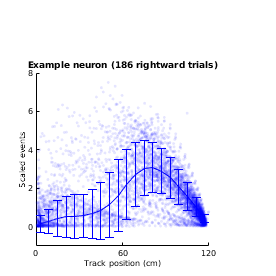


figure_format([1.8 1.8]);
Utils.printto('events_figs/rasters', 'one_cell_variability_nobins_errbars.pdf');

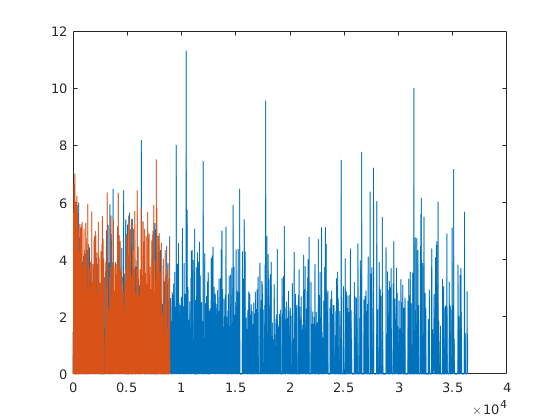

figure;
plot(S.tracesEvents.events_transients(:,90));
hold on;
plot(tr);

function pts = cofluct_lines(tensor)
[N, K, T] = size(tensor);
pts = zeros(N, T);
for n = 1:N
    for t = 1:T
        run = tensor(n, :, t);
        if std(run) < eps
            pts(n, t) = nan;
        else
            [~, pts(n, t)] = max(run);
        end
    end
end
end

function cofluct_lines_plot(tensor)
[N, K, T] = size(tensor);
pts = cofluct_lines(tensor);
hold on;
for t = 1:T
    plot(pts(:,t) + (t-1)*K, 1:N, '.w');
end
end

function cofluct_lines_plot_page(matrix)
tensor = reshape(matrix, size(matrix,1), size(matrix,2), 1);
cofluct_lines_plot(tensor);
end